# **第四章 极限学习机**

## 4.1  极限学习机简介

        极限学习机（Extreme Learning Machine, ELM），也称“极速学习机”，由新加坡南洋理工大学黄广斌（GuangBin Huang）教授于2006年提出。极限学习机模型的拓扑结构为一个典型的三层前向型神经网络，如图4.1所示。

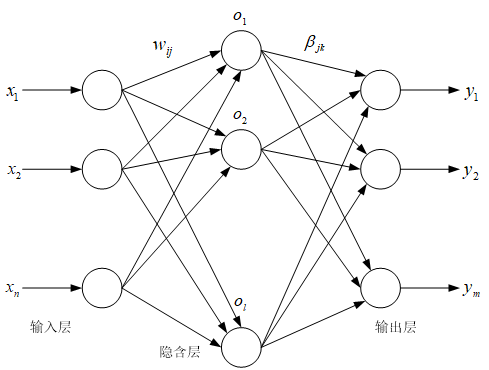

图1 极限学习机模型的拓扑结构

        因此，与BP神经网络类似，极限学习机的训练过程也是寻找到一组合适的连接权值和阈值参数，能够使得将训练集样本输入X送入模型后，在输出端得到的预测值Y与相应的真实值Z之间的误差足够小。

        与BP神经网络采用的多轮迭代修正参数不同，极限学习机在训练过程无需迭代，仅通过求解一个线性方程组即可找到一组合适的连接权值和阈值参数。因此，与BP神经网络相比，极限学习机的训练速度非常快，这也是为什么该方法能够称之为“极限/极速”（Extreme）的原因。

        极限学习机的工作原理如下：

- 首先，随机产生一组输入层与隐含层之间的连接权值$W$，利用BP神经网络前向传播的方法可以计算出隐含层神经元的输出矩阵$H$，计算公式如下；

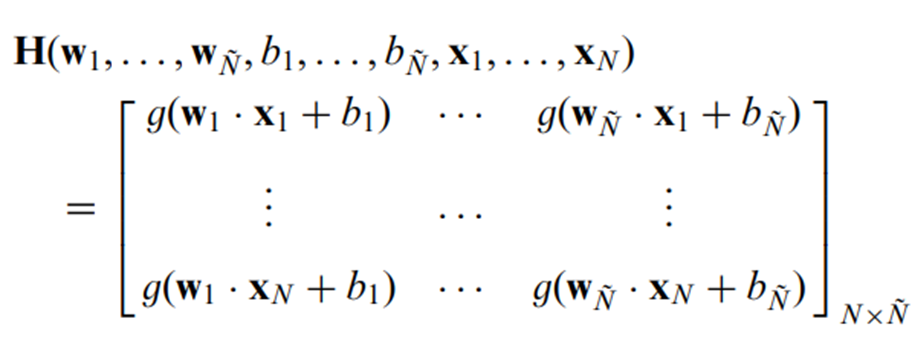

- 其次，假设隐含层与输出层之间的连接权值为$\beta$，训练集样本输出真实值为$T$，那么$\beta$可以通过求解下面的线性方程组得到：

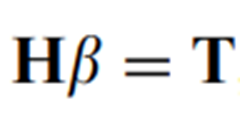

        如图2所示，黄广斌教授团队经过一系列的研究，在理论方面证明了极限学习机的两点结论：

- 若隐含层神经元个数可以无限大，那么极限学习机可以零误差逼近任意非线性关系；

- 若隐含层神经元个数≤训练集样本数，那么极限学习机可以将逼近误差控制在一个很小的范围内。

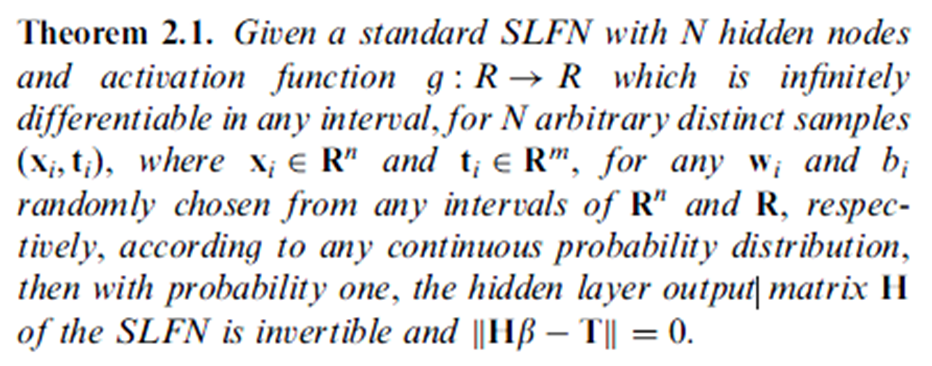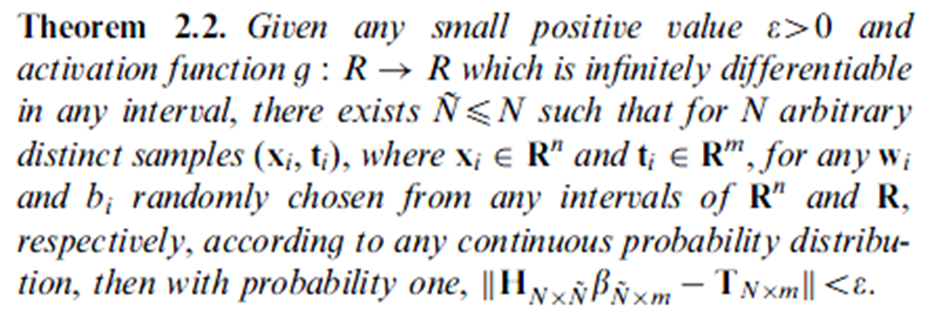

图2 极限学习机的理论证明

        综上所述，如图3所示，极限学习机的建模流程主要包括以下三个步骤：

- 随机产生一组输入层与隐含层之间的连接权值矩阵；

- 前向传播计算隐含层神经元输出矩阵；

- 求解线性方程组计算出隐含层与输出层之间的连接权值矩阵。

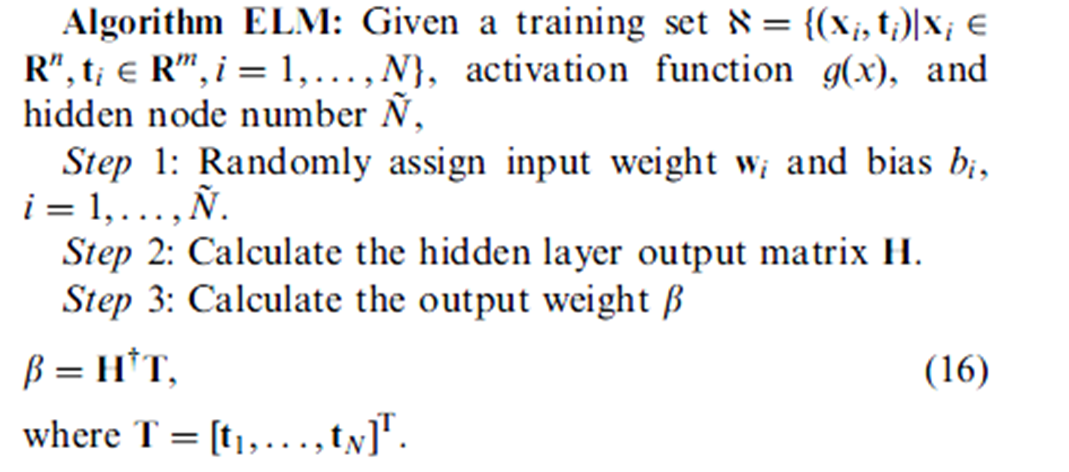

图3 极限学习机的建模流程

## 4.2 案例1：基于极限学习机的回归拟合——近红外光谱汽油辛烷值预测

- **数据集导入**

  % 导入数据
  load spectra_data.mat

- **训练集/测试集划分**

% 2. 随机产生训练集和测试集
  temp = randperm(size(NIR,1));
  k = 50

k = 50

  % 训练集——k个样本
  P_train = NIR(temp(1:k),:)';
  T_train = octane(temp(1:k),:)';
  % 测试集——60-k个样本
  P_test = NIR(temp(k+1:end),:)';
  T_test = octane(temp(k+1:end),:)';
  N = size(P_test,2);

- **数据归一化**

  % 数据归一化
  % 训练集
  [Pn_train,inputps] = mapminmax(P_train);
  Pn_test = mapminmax('apply',P_test,inputps);
  % 测试集
  [Tn_train,outputps] = mapminmax(T_train);
  Tn_test = mapminmax('apply',T_test,outputps);

- **ELM模型创建与训练**

         利用elmtrain()函数可以创建并训练ELM，由于汽油辛烷值的预测属于回归、拟合问题，因此，这里将参数TYPE设为0（默认即可）。同时，还需设定隐含层神经元个数及激活函数类型。

  % ELM创建/训练
  h = 30;
  [IW,B,LW,TF,TYPE] = elmtrain(Pn_train,Tn_train,h,'sig',0);

- **ELM模型预测**

        当ELM训练完成后，利用elmpredict()函数便可以对测试集进行仿真测试。需要说明的是，参数TF及TYPE需与elmtrain()函数中设定的参数保持一致。

  % ELM仿真测试
  tn_sim = elmpredict(Pn_test,IW,B,LW,TF,TYPE);
  % 反归一化
  T_sim = mapminmax('reverse',tn_sim,outputps);

- **性能评价**

        ELM仿真测试结束后，通过计算均方误差$E$及决定系数$R^2$，便可以对ELM的性能进行评价。具体程序如下：

  % 结果对比
  result = [T_test' T_sim'];
  % 均方误差
  E = mse(T_sim - T_test);
  % 决定系数
  N = length(T_test);
  R2=(N*sum(T_sim.*T_test)-sum(T_sim)*sum(T_test))^2/((N*sum((T_sim).^2)-(sum(T_sim))^2)*(N*sum((T_test).^2)-(sum(T_test))^2)); 

- **结果绘图可视化**

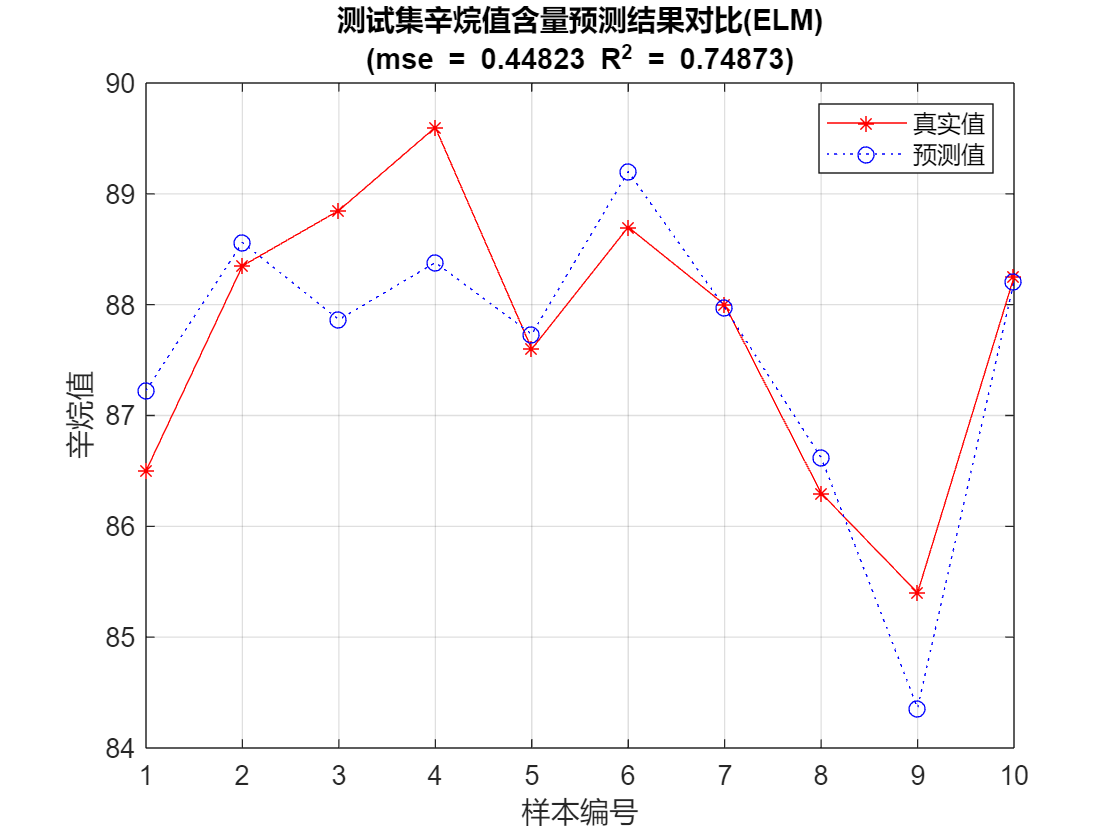

  % 绘图
  figure(1)
  plot(1:N,T_test,'r-*',1:N,T_sim,'b:o')
  grid on
  legend('真实值','预测值')
  xlabel('样本编号')
  ylabel('辛烷值')
  string = {'测试集辛烷值含量预测结果对比(ELM)';['(mse = ' num2str(E) ' R^2 = ' num2str(R2) ')']};
  title(string)

## 4.3 案例2：基于极限学习机的分类识别——鸢尾花分类

- **数据集导入**

  % 导入数据
  load iris_data.mat

- **训练集/测试集划分**

        采用随机法产生训练集和测试集，其中训练集包含120个样本，测试集包含30个样本。

  % 随机产生训练集和测试集
  P_train = [];
  T_train = [];
  P_test = [];
  T_test = [];

  for i = 1:3
      temp_input = features((i-1)*50+1:i*50,:);
      temp_output = classes((i-1)*50+1:i*50,:);
      n = randperm(50);
      a = 40;
      % 训练集——120个样本
      P_train = [P_train temp_input(n(1:a),:)'];
      T_train = [T_train temp_output(n(1:a),:)'];
      % 测试集——30个样本
      P_test = [P_test temp_input(n(a+1:50),:)'];
      T_test = [T_test temp_output(n(a+1:50),:)'];
  end

- **ELM模型创建与训练**

        利用elmtrain()函数可以创建并训练ELM，由于鸢尾花的种类识别属于分类问题，因此，这里将参数TYPE设为1（默认即可）。同时，还需设定隐含层神经元个数及激活函数类型。

  %% ELM创建/训练
  m = 20;
  [IW,B,LW,TF,TYPE] = elmtrain(P_train,T_train,m,'sig',1);

- **ELM模型预测**

        当ELM训练完成后，利用elmpredict()函数便可以对测试集进行仿真测试。如前文所述，参数TF及TYPE需与elmtrain()函数中设定的参数保持一致。

  % ELM仿真测试
  T_sim_1 = elmpredict(P_train,IW,B,LW,TF,TYPE);
  T_sim_2 = elmpredict(P_test,IW,B,LW,TF,TYPE);

- **性能指标**

        ELM仿真测试结束后，通过计算训练集和测试集的正确率，从而对ELM的性能进行评价。具体程序如下：

  % 结果对比
  result_1 = [T_train' T_sim_1'];
  result_2 = [T_test' T_sim_2'];
  
  % 训练集正确率
  k1 = length(find(T_train == T_sim_1));
  n1 = length(T_train);
  Accuracy_1 = k1 / n1 * 100;
  disp(['训练集正确率Accuracy = ' num2str(Accuracy_1) '%(' num2str(k1) '/' num2str(n1) ')'])

训练集正确率Accuracy = 98.3333%(118/120)


  
  % 测试集正确率
  k2 = length(find(T_test == T_sim_2));
  n2 = length(T_test);
  Accuracy_2 = k2 / n2 * 100;
  disp(['测试集正确率Accuracy = ' num2str(Accuracy_2) '%(' num2str(k2) '/' num2str(n2) ')'])

测试集正确率Accuracy = 96.6667%(29/30)


- **结果绘图可视化**

        为了便于直观地对结果进行分析、比较，这里以图形的形式给出最终的结果。具体程序如下：

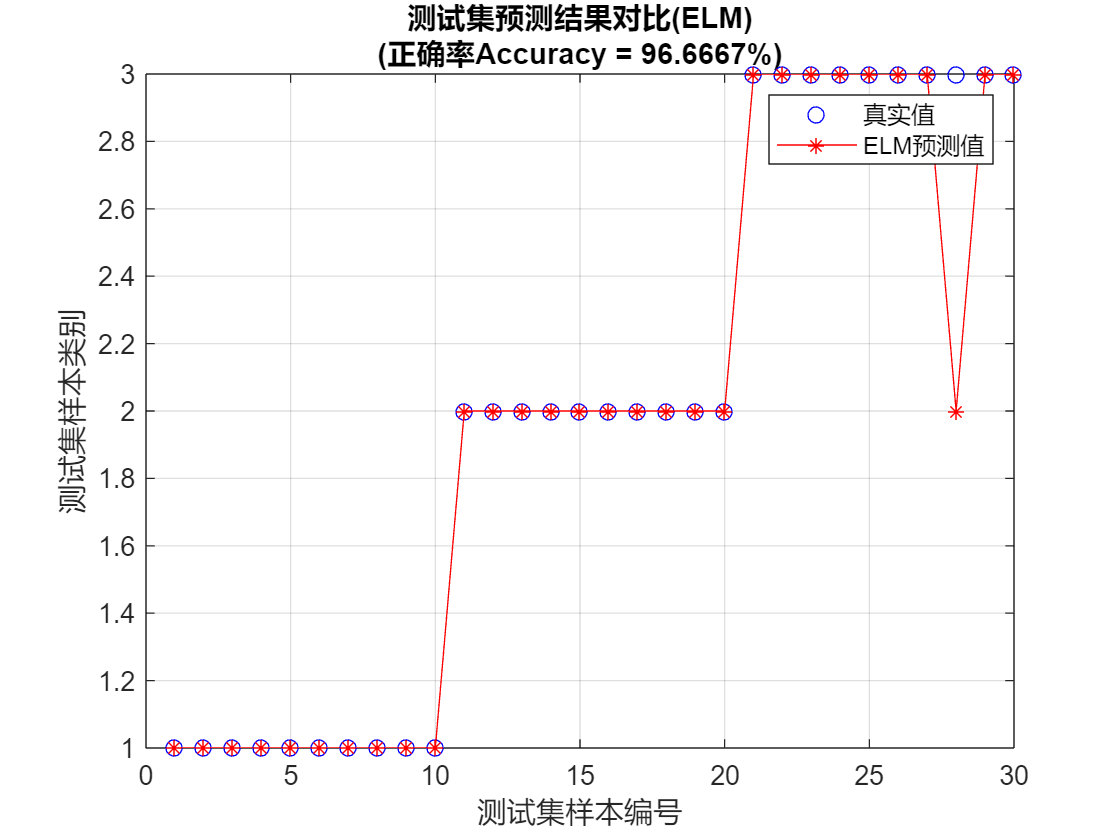

  % 绘图
  figure
  plot(1:30,T_test,'bo',1:30,T_sim_2,'r-*')
  grid on
  xlabel('测试集样本编号')
  ylabel('测试集样本类别')
  string = {'测试集预测结果对比(ELM)';['(正确率Accuracy = ' num2str(Accuracy_2) '%)' ]};
  title(string)
  legend('真实值','ELM预测值')

## Appendix-1: ELM模型创建与训练子函数

    function [IW,B,LW,TF,TYPE] = elmtrain(P,T,N,TF,TYPE)
    
        % ELMTRAIN Create and Train a Extreme Learning Machine
        % Syntax
        % [IW,B,LW,TF,TYPE] = elmtrain(P,T,N,TF,TYPE)
        % Description
        % Input
        % P   - Input Matrix of Training Set  (R*Q)
        % T   - Output Matrix of Training Set (S*Q)
        % N   - Number of Hidden Neurons (default = Q)
        % TF  - Transfer Function:
        %       'sig' for Sigmoidal function (default)
        %       'sin' for Sine function
        %       'hardlim' for Hardlim function
        % TYPE - Regression (0,default) or Classification (1)
        % Output
        % IW  - Input Weight Matrix (N*R)
        % B   - Bias Matrix  (N*1)
        % LW  - Layer Weight Matrix (N*S)
        % Example
        % Regression:
        % [IW,B,LW,TF,TYPE] = elmtrain(P,T,20,'sig',0)
        % Y = elmtrain(P,IW,B,LW,TF,TYPE)
        % Classification
        % [IW,B,LW,TF,TYPE] = elmtrain(P,T,20,'sig',1)
        % Y = elmtrain(P,IW,B,LW,TF,TYPE)
        % See also ELMPREDICT
        % Yu Lei,11-7-2010
        % Copyright www.matlabsky.com
        % $Revision:1.0 $
        if nargin < 2
            error('ELM:Arguments','Not enough input arguments.');
        end
        if nargin < 3
            N = size(P,2);
        end
        if nargin < 4
            TF = 'sig';
        end
        if nargin < 5
            TYPE = 0;
        end
        if size(P,2) ~= size(T,2)
            error('ELM:Arguments','The columns of P and T must be same.');
        end
        [R,Q] = size(P);
        if TYPE  == 1
            T  = ind2vec(T);
        end
        [S,Q] = size(T);
        % Randomly Generate the Input Weight Matrix
        IW = rand(N,R) * 2 - 1;
        % Randomly Generate the Bias Matrix
        B = rand(N,1);
        BiasMatrix = repmat(B,1,Q);
        % Calculate the Layer Output Matrix H
        tempH = IW * P + BiasMatrix;
        switch TF
            case 'sig'
                H = 1 ./ (1 + exp(-tempH));
            case 'sin'
                H = sin(tempH);
            case 'hardlim'
                H = hardlim(tempH);
        end
        % Calculate the Output Weight Matrix
        LW = pinv(H') * T';

    end

## Appendix-2: ELM模型**预测子函数**

    function Y = elmpredict(P,IW,B,LW,TF,TYPE)
        
        % ELMPREDICT Simulate a Extreme Learning Machine
        % Syntax
        % Y = elmtrain(P,IW,B,LW,TF,TYPE)
        % Description
        % Input
        % P   - Input Matrix of Training Set  (R*Q)
        % IW  - Input Weight Matrix (N*R)
        % B   - Bias Matrix  (N*1)
        % LW  - Layer Weight Matrix (N*S)
        % TF  - Transfer Function:
        %       'sig' for Sigmoidal function (default)
        %       'sin' for Sine function
        %       'hardlim' for Hardlim function
        % TYPE - Regression (0,default) or Classification (1)
        % Output
        % Y   - Simulate Output Matrix (S*Q)
        % Example
        % Regression:
        % [IW,B,LW,TF,TYPE] = elmtrain(P,T,20,'sig',0)
        % Y = elmtrain(P,IW,B,LW,TF,TYPE)
        % Classification
        % [IW,B,LW,TF,TYPE] = elmtrain(P,T,20,'sig',1)
        % Y = elmtrain(P,IW,B,LW,TF,TYPE)
        % See also ELMTRAIN
        % Yu Lei,11-7-2010
        % Copyright www.matlabsky.com
        % $Revision:1.0 $
        if nargin < 6
            error('ELM:Arguments','Not enough input arguments.');
        end
        % Calculate the Layer Output Matrix H
        Q = size(P,2);
        BiasMatrix = repmat(B,1,Q);
        tempH = IW * P + BiasMatrix;
        switch TF
            case 'sig'
                H = 1 ./ (1 + exp(-tempH));
            case 'sin'
                H = sin(tempH);
            case 'hardlim'
                H = hardlim(tempH);
        end
        % Calculate the Simulate Output
        Y = (H' * LW)';
        if TYPE == 1
            temp_Y = zeros(size(Y));
            for i = 1:size(Y,2)
                [~,index] = max(Y(:,i));
                temp_Y(index,i) = 1;
            end
            Y = vec2ind(temp_Y);
        end

    end